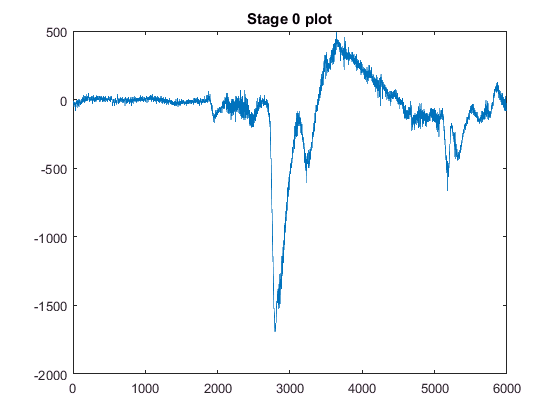

% part2
figure(1)
plot(stage0.Data(:,1));
title('Stage 0 plot');

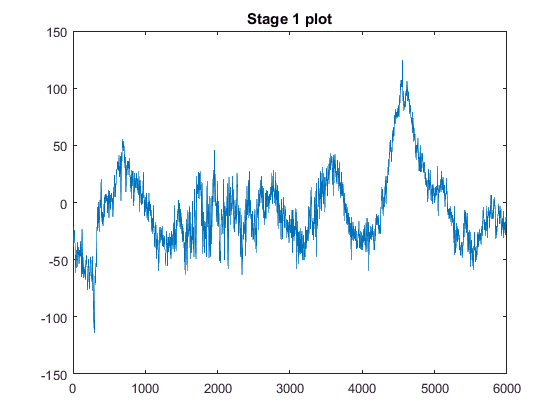

figure(2)
plot(stage1.Data(:,1));
title('Stage 1 plot');

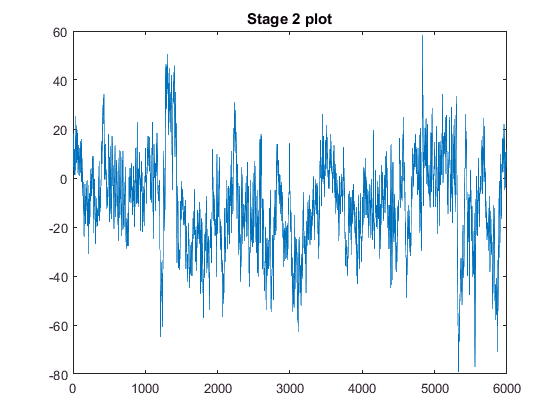

figure(3)
plot(stage2.Data(:,1));
title('Stage 2 plot');

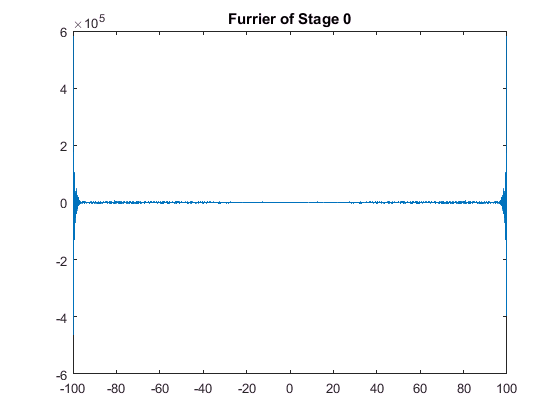

% part3
% stage 0
d0 = fft(stage0.Data(:,1));
fs0 = stage0.Fs(1);
T0 = 1/fs0;
l0 = length(d0);
ff0 = (-l0/2:l0/2-1)*fs0/l0;
t0 = 0:T0:(l0-1)*T0;
figure(4);
plot(ff0,real(d0));
title('Furrier of Stage 0');

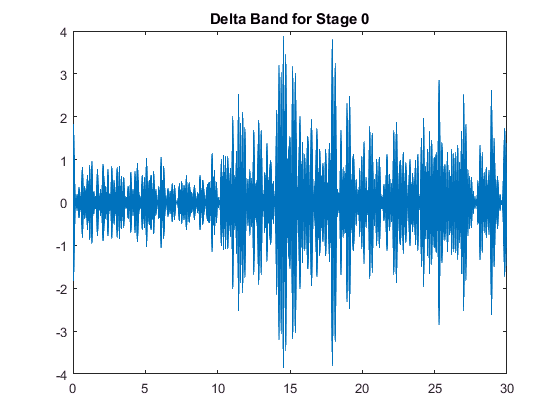

d0delta = d0;
d0delta(~(-1<ff0 & ff0<-4) & ~(ff0>1 & ff0<4)) = 0;
delta0 = ifft(d0delta);
figure(5);
plot(t0,real(delta0));
title('Delta Band for Stage 0');

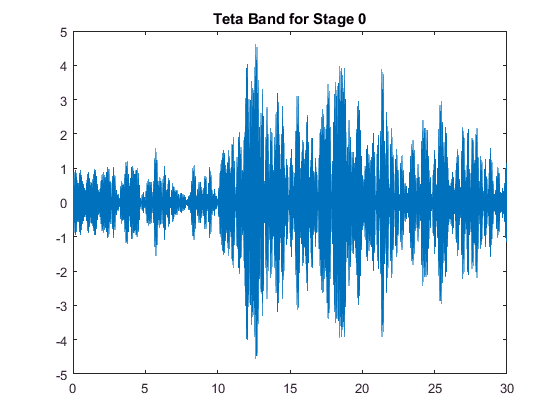

d0teta = d0;
d0teta(~(-4<ff0 & ff0<-8) & ~(ff0>4 & ff0<8)) = 0;
teta0 = ifft(d0teta);
figure(6);
plot(t0,real(teta0));
title('Teta Band for Stage 0');

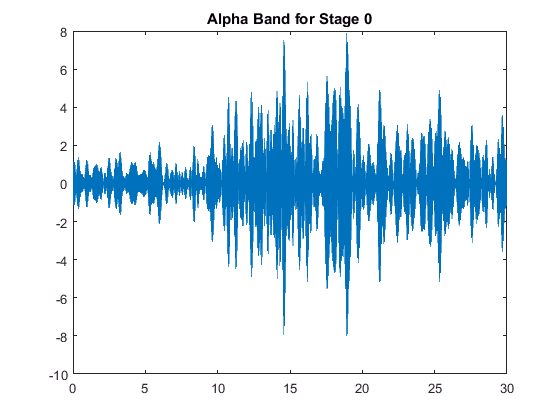

d0alpha = d0;
d0alpha(~(-8<ff0 & ff0<-13) & ~(ff0>8 & ff0<13)) = 0;
alpha0 = ifft(d0alpha);
figure(7);
plot(t0,real(alpha0));
title('Alpha Band for Stage 0');

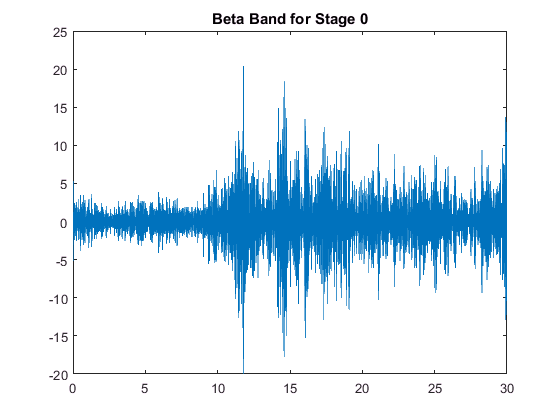

d0beta = d0;
d0beta(~(-13<ff0 & ff0<-30) & ~(ff0>13 & ff0<30)) = 0;
beta0 = ifft(d0beta);
figure(8);
plot(t0,real(beta0));
title('Beta Band for Stage 0');

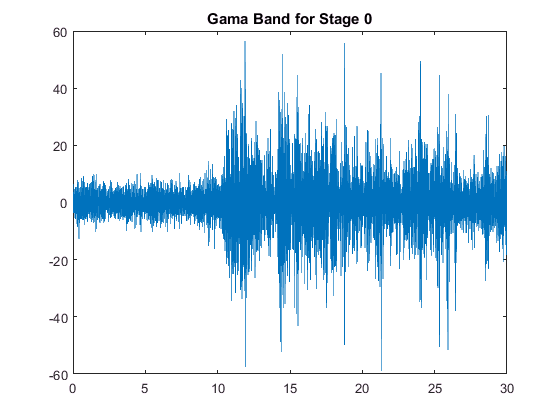

d0gama = d0;
d0gama(~(-30<ff0 & ff0<-80) & ~(ff0>30 & ff0<80)) = 0;
gama0 = ifft(d0gama);
figure(9);
plot(t0,real(gama0));
title('Gama Band for Stage 0');

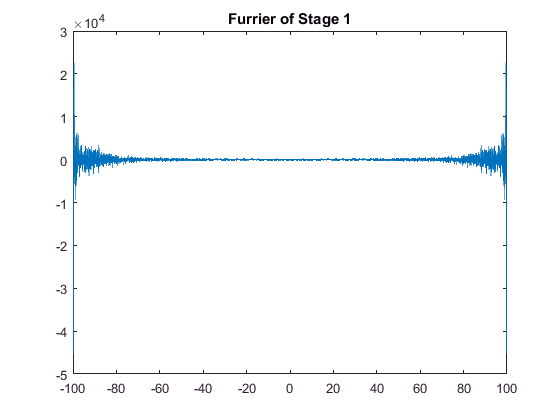

% stage 1
d1 = fft(stage1.Data(:,1));
fs1 = stage1.Fs(1);
T1 = 1/fs1;
l1 = length(d1);
ff1 = (-l1/2:l1/2-1)*fs1/l1;
t1 = 0:T1:(l1-1)*T1;
figure(10);
plot(ff1,real(d1));
title('Furrier of Stage 1');

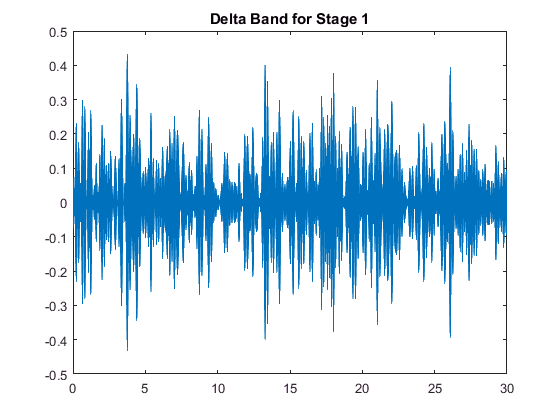

d1delta = d1;
d1delta(~(-1<ff1 & ff1<-4) & ~(ff1>1 & ff1<4)) = 0;
delta1 = ifft(d1delta);
figure(11);
plot(t1,real(delta1));
title('Delta Band for Stage 1');

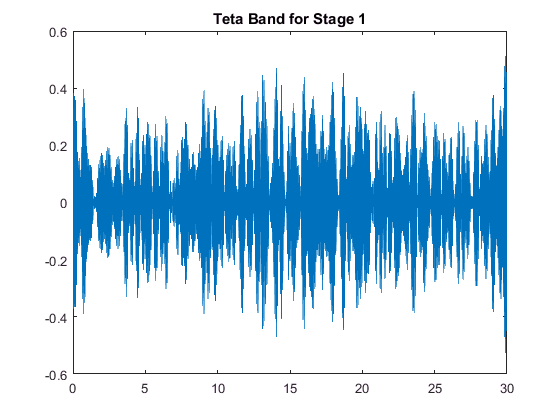

d1teta = d1;
d1teta(~(-4<ff1 & ff1<-8) & ~(ff1>4 & ff1<8)) = 0;
teta1 = ifft(d1teta);
figure(12);
plot(t1,real(teta1));
title('Teta Band for Stage 1');

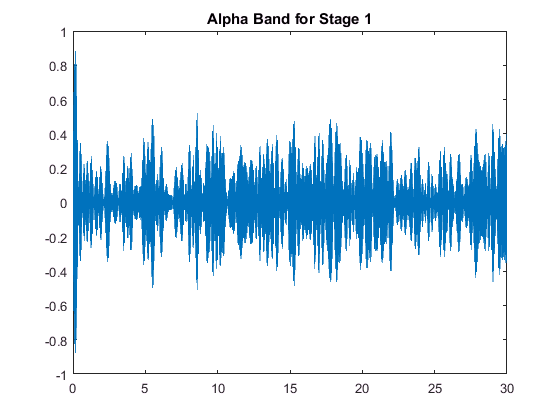

d1alpha = d1;
d1alpha(~(-8<ff1 & ff1<-13) & ~(ff1>8 & ff1<13)) = 0;
alpha1 = ifft(d1alpha);
figure(13);
plot(t1,real(alpha1));
title('Alpha Band for Stage 1');

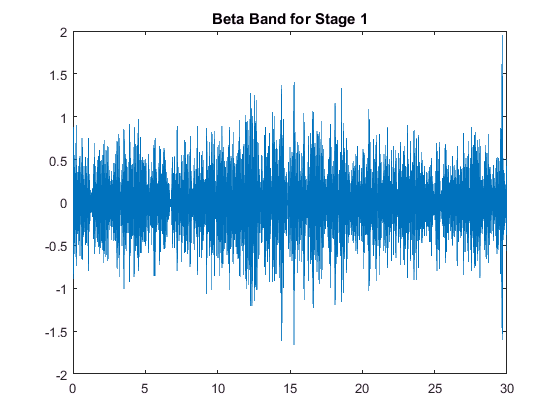

d1beta = d1;
d1beta(~(-13<ff1 & ff1<-30) & ~(ff1>13 & ff1<30)) = 0;
beta1 = ifft(d1beta);
figure(14);
plot(t1,real(beta1));
title('Beta Band for Stage 1');

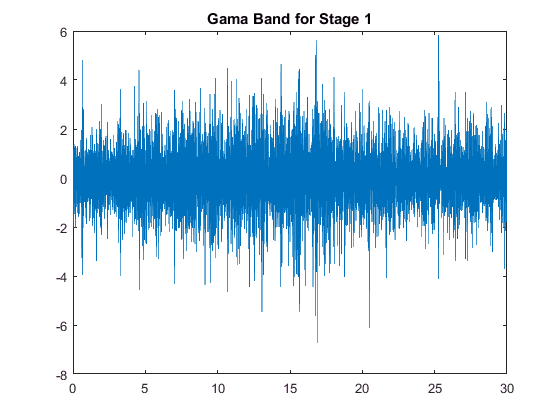

d1gama = d1;
d1gama(~(-30<ff1 & ff1<-80) & ~(ff1>30 & ff1<80)) = 0;
gama1 = ifft(d1gama);
figure(15);
plot(t1,real(gama1));
title('Gama Band for Stage 1');

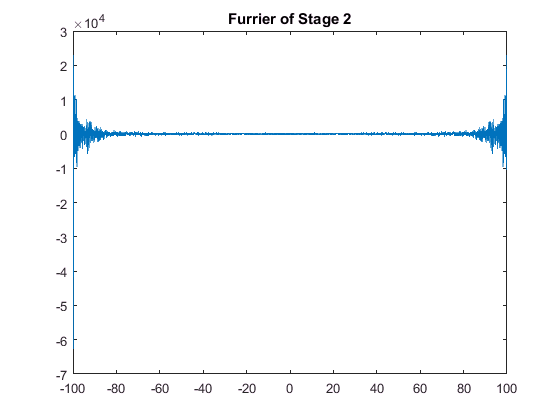

% stage 2
d2 = fft(stage2.Data(:,1));
fs2 = stage2.Fs(1);
T2 = 1/fs2;
l2 = length(d2);
ff2 = (-l2/2:l2/2-1)*fs2/l2;
t2 = 0:T2:(l2-1)*T2;
figure(16);
plot(ff2,real(d2));
title('Furrier of Stage 2');

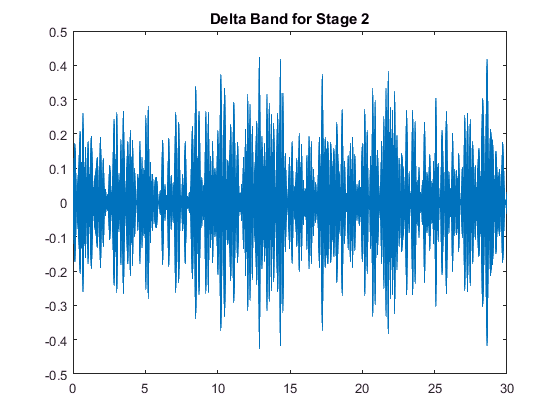

d2delta = d2;
d2delta(~(-1<ff2 & ff2<-4) & ~(ff2>1 & ff2<4)) = 0;
delta2 = ifft(d2delta);
figure(17);
plot(t2,real(delta2));
title('Delta Band for Stage 2');

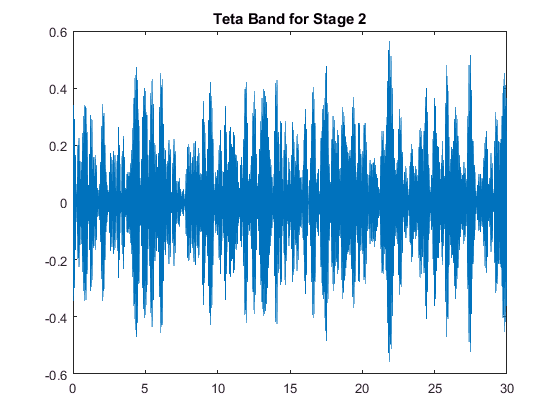

d2teta = d2;
d2teta(~(-4<ff2 & ff2<-8) & ~(ff2>4 & ff2<8)) = 0;
teta2 = ifft(d2teta);
figure(18);
plot(t2,real(teta2));
title('Teta Band for Stage 2');

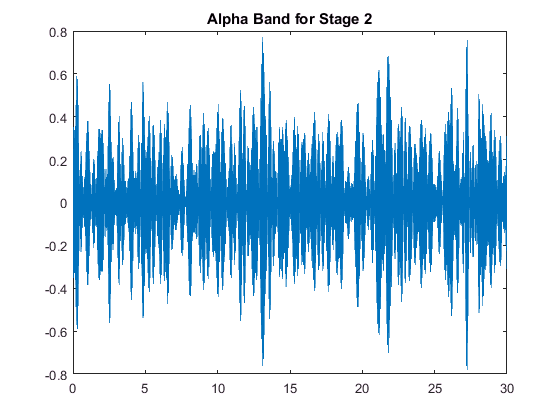

d2alpha = d2;
d2alpha(~(-8<ff2 & ff2<-13) & ~(ff2>8 & ff2<13)) = 0;
alpha2 = ifft(d2alpha);
figure(19);
plot(t2,real(alpha2));
title('Alpha Band for Stage 2');

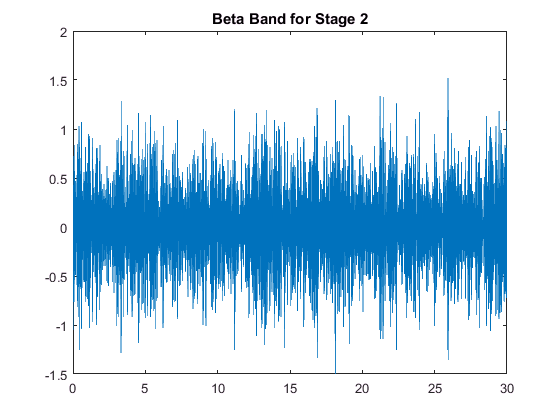

d2beta = d2;
d2beta(~(-13<ff2 & ff2<-30) & ~(ff2>13 & ff2<30)) = 0;
beta2 = ifft(d2beta);
figure(20);
plot(t2,real(beta2));
title('Beta Band for Stage 2');

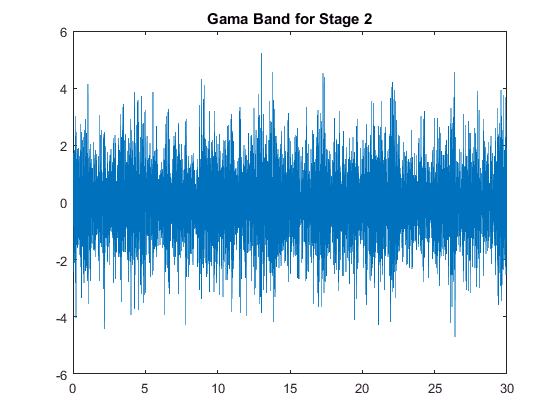

d2gama = d2;
d2gama(~(-30<ff2 & ff2<-80) & ~(ff2>30 & ff2<80)) = 0;
gama2 = ifft(d2gama);
figure(21);
plot(t2,real(gama2));
title('Gama Band for Stage 2');

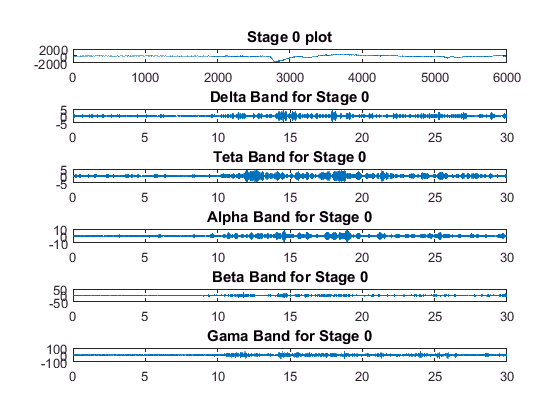

% part3 compare last results
% stage 0
figure(22)
subplot(6,1,1);
plot(stage0.Data(:,1));
title('Stage 0 plot');
subplot(6,1,2);
plot(t0,real(delta0));
title('Delta Band for Stage 0');
subplot(6,1,3);
plot(t0,real(teta0));
title('Teta Band for Stage 0');
subplot(6,1,4);
plot(t0,real(alpha0));
title('Alpha Band for Stage 0');
subplot(6,1,5);
plot(t0,real(beta0));
title('Beta Band for Stage 0');
subplot(6,1,6);
plot(t0,real(gama0));
title('Gama Band for Stage 0');

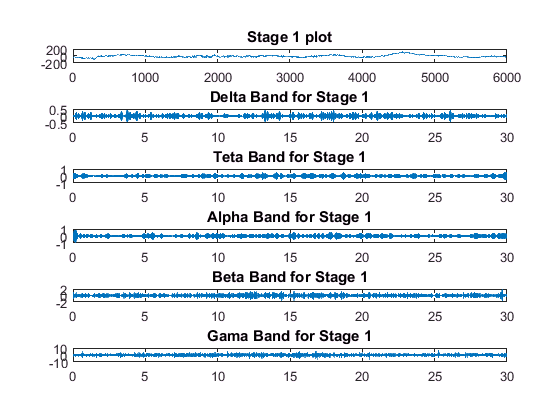

% stage 1
figure(23)
subplot(6,1,1);
plot(stage1.Data(:,1));
title('Stage 1 plot');
subplot(6,1,2);
plot(t1,real(delta1));
title('Delta Band for Stage 1');
subplot(6,1,3);
plot(t1,real(teta1));
title('Teta Band for Stage 1');
subplot(6,1,4);
plot(t1,real(alpha1));
title('Alpha Band for Stage 1');
subplot(6,1,5);
plot(t1,real(beta1));
title('Beta Band for Stage 1');
subplot(6,1,6);
plot(t1,real(gama1));
title('Gama Band for Stage 1');

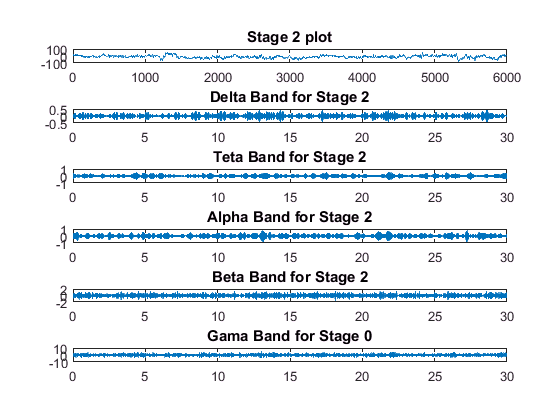

% stage 2
figure(24)
subplot(6,1,1);
plot(stage2.Data(:,1));
title('Stage 2 plot');
subplot(6,1,2);
plot(t2,real(delta2));
title('Delta Band for Stage 2');
subplot(6,1,3);
plot(t2,real(teta2));
title('Teta Band for Stage 2');
subplot(6,1,4);
plot(t2,real(alpha2));
title('Alpha Band for Stage 2');
subplot(6,1,5);
plot(t2,real(beta2));
title('Beta Band for Stage 2');
subplot(6,1,6);
plot(t2,real(gama2));
title('Gama Band for Stage 0');

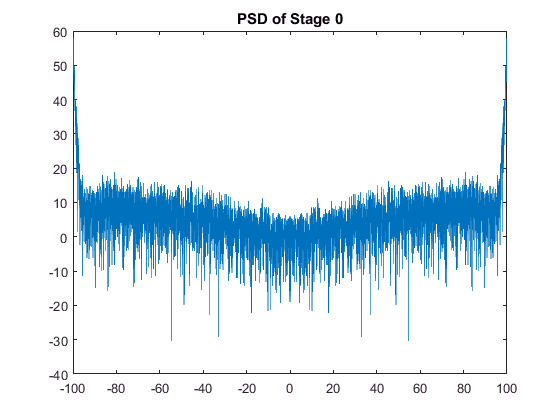

%part 4
%stage 0
p0 = d0;
psd0 = (1/(fs0*l0)) * abs(p0).^2;
psd0(2:end-1) = 2*psd0(2:end-1);
figure(25);
plot(ff0,10*log10(psd0));
title('PSD of Stage 0');

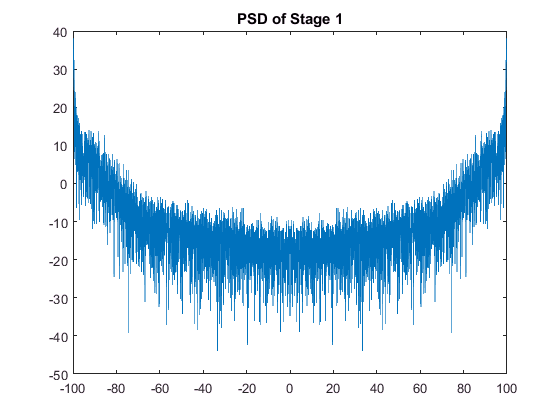

%stage 1
p1 = d1;
psd1 = (1/(fs1*l0)) * abs(p1).^2;
psd1(2:end-1) = 2*psd1(2:end-1);
figure(26);
plot(ff1,10*log10(psd1));
title('PSD of Stage 1');

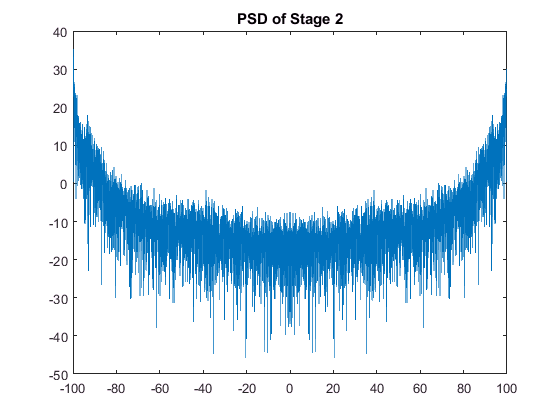

%stage 2
p2 = d2;
psd2 = (1/(fs2*l0)) * abs(p2).^2;
psd2(2:end-1) = 2*psd2(2:end-1);
figure(27);
plot(ff2,10*log10(psd2));
title('PSD of Stage 2');

%part5 power of each band
% stage 0
p0d = sum(real(delta0).^2);
p0t = sum(real(teta0).^2);
p0a = sum(real(alpha0).^2);
p0b = sum(real(beta0).^2);
p0g = sum(real(gama0).^2);
p0 = {'Stage 0' p0d p0t p0a p0b p0g};
% stage 1
p1d = sum(real(delta1).^2);
p1t = sum(real(teta1).^2);
p1a = sum(real(alpha1).^2);
p1b = sum(real(beta1).^2);
p1g = sum(real(gama1).^2);
p1 = {'Stage 1' p1d p1t p1a p1b p1g};
% stage 2
p2d = sum(real(delta2).^2);
p2t = sum(real(teta2).^2);
p2a = sum(real(alpha2).^2);
p2b = sum(real(beta2).^2);
p2g = sum(real(gama2).^2);
p2 = {'Stage 2' p2d p2t p2a p2b p2g};
disp('     Power       Delta            Teta            Alpha           Beta       Gama');

     Power       Delta            Teta            Alpha           Beta       Gama


disp(p0);

    'Stage 0'    [5.5188e+03]    [7.9914e+03]    [1.5529e+04]    [6.0035e+04]    [5.1187e+05]



disp(p1);

    'Stage 1'    [99.4084]    [156.3010]    [175.6388]    [809.6817]    [1.0118e+04]



disp(p2);

    'Stage 2'    [128.6468]    [171.7581]    [256.7347]    [1.0365e+03]    [9.5969e+03]



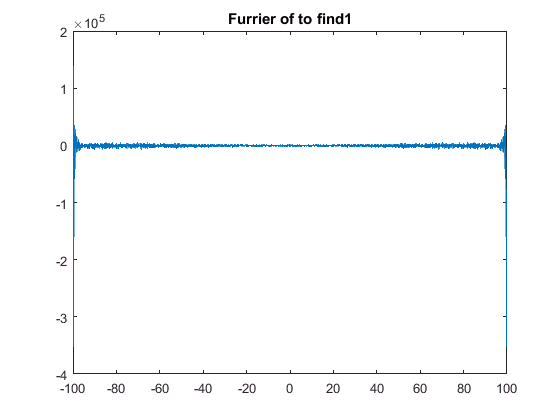

% part6
% to_find1
x1 = fft(to_find.Data(:,1));
fsx1 = to_find.Fs(1);
Tx1 = 1/fsx1;
lx1 = length(x1);
ffx1 = (-lx1/2:lx1/2-1)*fsx1/lx1;
tx1 = 0:Tx1:(lx1-1)*Tx1;
figure(28);
plot(ffx1,real(x1));
title('Furrier of to find1');

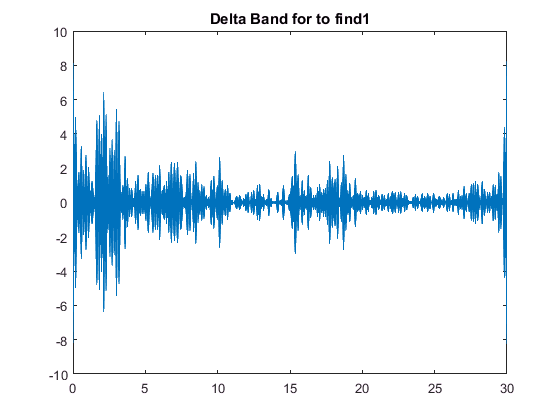

x1delta = x1;
x1delta(~(-1<ffx1 & ffx1<-4) & ~(ffx1>1 & ffx1<4)) = 0;
deltax1 = ifft(x1delta);
figure(29);
plot(tx1,real(deltax1));
title('Delta Band for to find1');

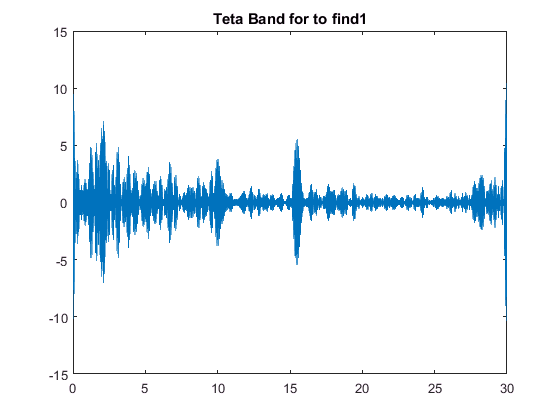

x1teta = x1;
x1teta(~(-4<ffx1 & ffx1<-8) & ~(ffx1>4 & ffx1<8)) = 0;
tetax1 = ifft(x1teta);
figure(30);
plot(tx1,real(tetax1));
title('Teta Band for to find1');

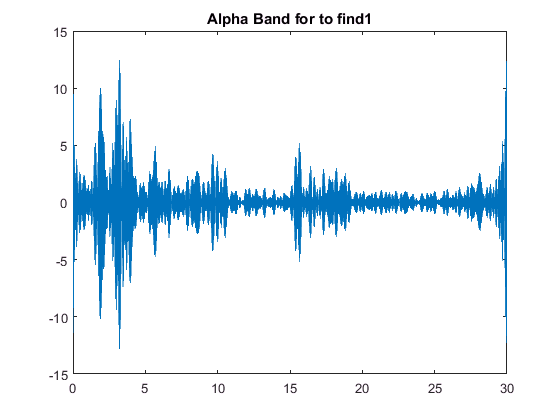

x1alpha = x1;
x1alpha(~(-8<ffx1 & ffx1<-13) & ~(ffx1>8 & ffx1<13)) = 0;
alphax1 = ifft(x1alpha);
figure(31);
plot(tx1,real(alphax1));
title('Alpha Band for to find1');

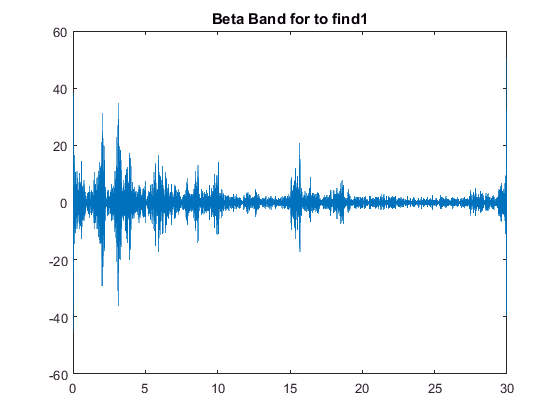

x1beta = x1;
x1beta(~(-13<ffx1 & ffx1<-30) & ~(ffx1>13 & ffx1<30)) = 0;
betax1 = ifft(x1beta);
figure(32);
plot(tx1,real(betax1));
title('Beta Band for to find1');

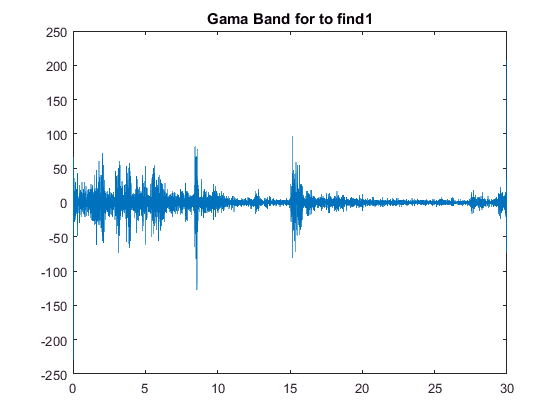

x1gama = x1;
x1gama(~(-30<ffx1 & ffx1<-80) & ~(ffx1>30 & ffx1<80)) = 0;
gamax1 = ifft(x1gama);
figure(33);
plot(tx1,real(gamax1));
title('Gama Band for to find1');

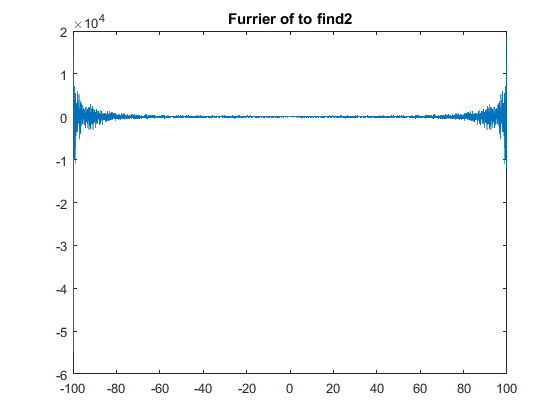

% to_find2
x2 = fft(to_find2.Data(:,1));
fsx2 = to_find2.Fs(1);
Tx2 = 1/fsx2;
lx2= length(x2);
ffx2 = (-lx2/2:lx2/2-1)*fsx2/lx2;
tx2 = 0:Tx2:(lx2-1)*Tx2;
figure(34);
plot(ffx2,real(x2));
title('Furrier of to find2');

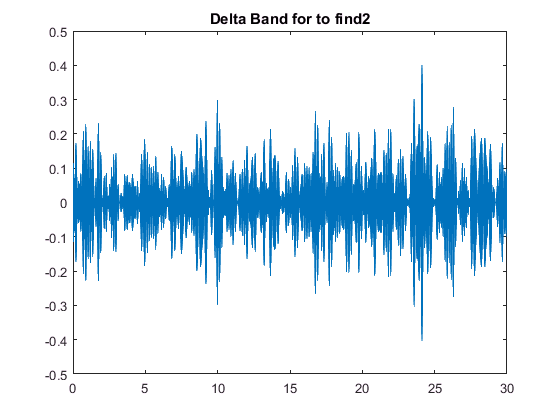

x2delta = x2;
x2delta(~(-1<ffx2 & ffx2<-4) & ~(ffx2>1 & ffx2<4)) = 0;
deltax2 = ifft(x2delta);
figure(35);
plot(tx2,real(deltax2));
title('Delta Band for to find2');

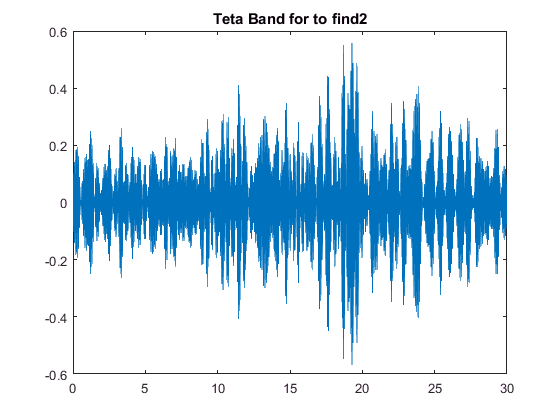

x2teta = x2;
x2teta(~(-4<ffx2 & ffx2<-8) & ~(ffx2>4 & ffx2<8)) = 0;
tetax2 = ifft(x2teta);
figure(36);
plot(tx2,real(tetax2));
title('Teta Band for to find2');

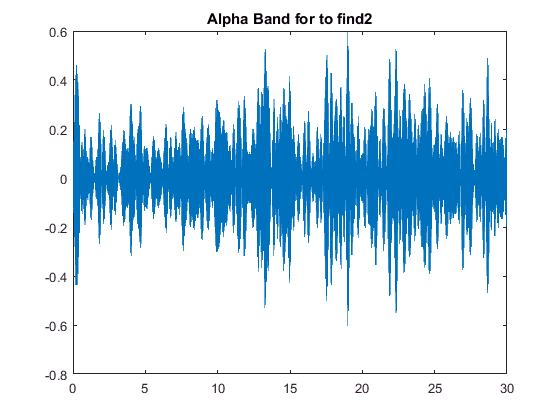

x2alpha = x2;
x2alpha(~(-8<ffx2 & ffx2<-13) & ~(ffx2>8 & ffx2<13)) = 0;
alphax2 = ifft(x2alpha);
figure(37);
plot(tx2,real(alphax2));
title('Alpha Band for to find2');

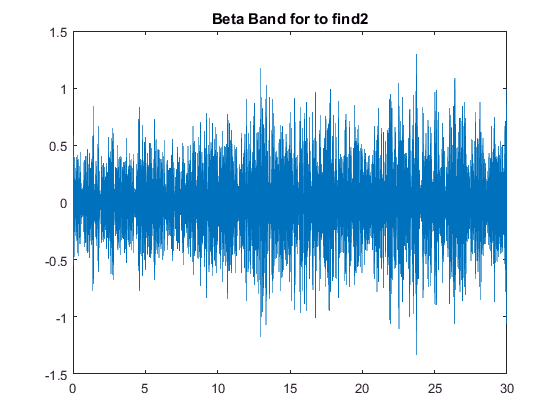

x2beta = x2;
x2beta(~(-13<ffx2 & ffx2<-30) & ~(ffx2>13 & ffx2<30)) = 0;
betax2 = ifft(x2beta);
figure(38);
plot(tx2,real(betax2));
title('Beta Band for to find2');

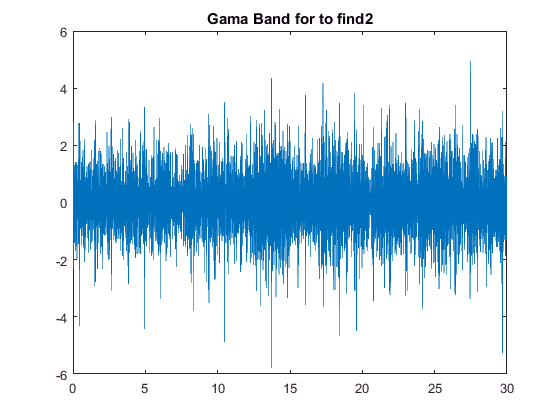

x2gama = x2;
x2gama(~(-30<ffx2 & ffx2<-80) & ~(ffx2>30 & ffx2<80)) = 0;
gamax2 = ifft(x2gama);
figure(39);
plot(tx2,real(gamax2));
title('Gama Band for to find2');

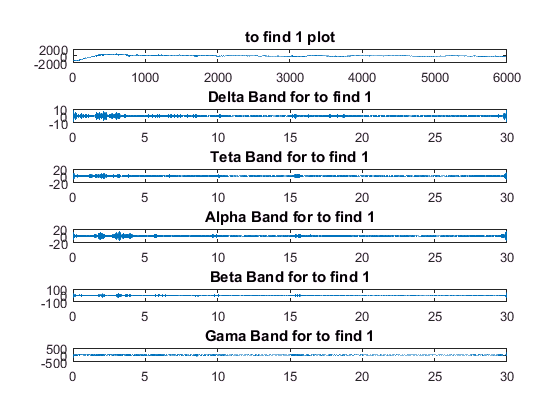

% part6 compare last part 6 results
% to find 1
figure(40)
subplot(6,1,1);
plot(to_find.Data(:,1));
title('to find 1 plot');
subplot(6,1,2);
plot(tx1,real(deltax1));
title('Delta Band for to find 1');
subplot(6,1,3);
plot(tx1,real(tetax1));
title('Teta Band for to find 1');
subplot(6,1,4);
plot(tx1,real(alphax1));
title('Alpha Band for to find 1');
subplot(6,1,5);
plot(tx1,real(betax1));
title('Beta Band for to find 1');
subplot(6,1,6);
plot(tx1,real(gamax1));
title('Gama Band for to find 1');

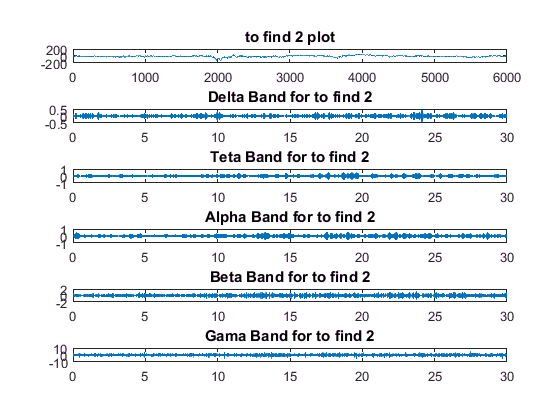

%to find 2
figure(41)
subplot(6,1,1);
plot(to_find2.Data(:,1));
title('to find 2 plot');
subplot(6,1,2);
plot(tx2,real(deltax2));
title('Delta Band for to find 2');
subplot(6,1,3);
plot(tx2,real(tetax2));
title('Teta Band for to find 2');
subplot(6,1,4);
plot(tx2,real(alphax2));
title('Alpha Band for to find 2');
subplot(6,1,5);
plot(tx2,real(betax2));
title('Beta Band for to find 2');
subplot(6,1,6);
plot(tx2,real(gamax2));
title('Gama Band for to find 2');

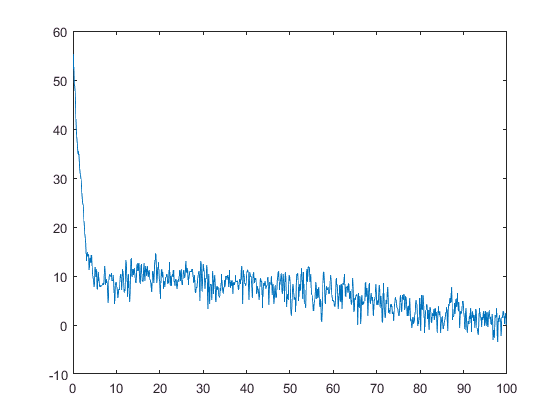

% use pwelch for stages then we compare next part
% stage 0
[pw0,freqw0] = pwelch(stage0.Data(:,1),[],[],[],fs0);
figure(42)
plot(freqw0,10*log10(pw0));

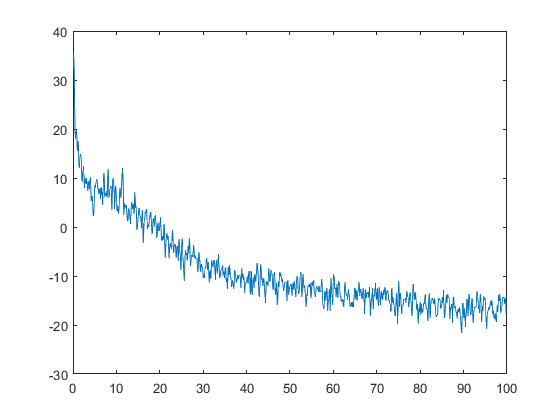

% stage 1
[pw1,freqw1] = pwelch(stage1.Data(:,1),[],[],[],fs1);
figure(43)
plot(freqw1,10*log10(pw1));

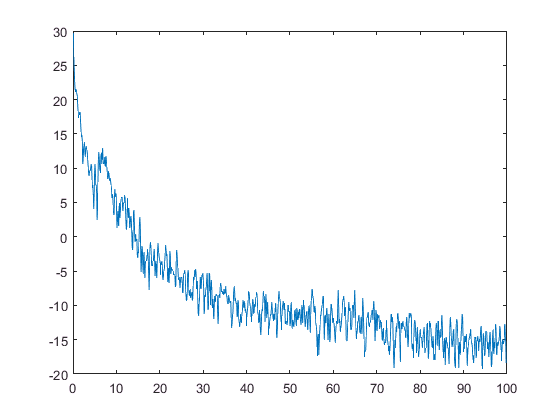

% stage 2
[pw2,freqw2] = pwelch(stage2.Data(:,1),[],[],[],fs2);
figure(44)
plot(freqw2,10*log10(pw2));

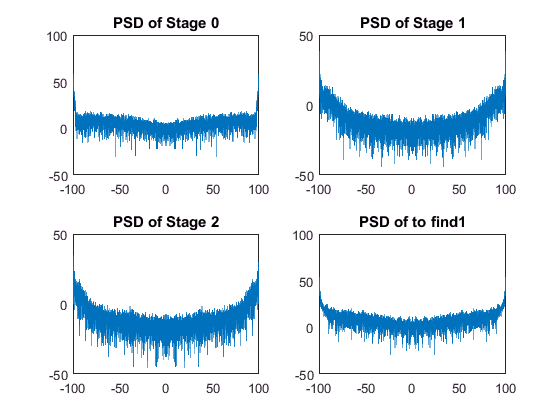

% psd for part 6 and compare
%to find 1
psx1 = x1;
psdx1 = (1/(fsx1*l0)) * abs(psx1).^2;
psdx1(2:end-1) = 2*psdx1(2:end-1);
figure(45);
subplot(2,2,1)
plot(ff0,10*log10(psd0));
title('PSD of Stage 0');
subplot(2,2,2)
plot(ff1,10*log10(psd1));
title('PSD of Stage 1');
subplot(2,2,3)
plot(ff2,10*log10(psd2));
title('PSD of Stage 2');
subplot(2,2,4)
plot(ffx1,10*log10(psdx1));
title('PSD of to find1');

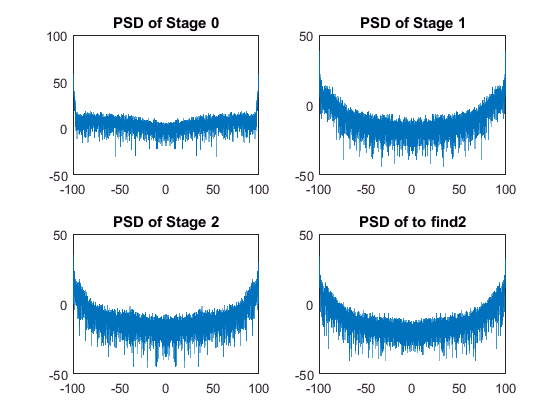

%to find 2
psx2 = x2;
psdx2 = (1/(fsx2*l0)) * abs(psx2).^2;
psdx2(2:end-1) = 2*psdx2(2:end-1);
figure(46);
subplot(2,2,1)
plot(ff0,10*log10(psd0));
title('PSD of Stage 0');
subplot(2,2,2)
plot(ff1,10*log10(psd1));
title('PSD of Stage 1');
subplot(2,2,3)
plot(ff2,10*log10(psd2));
title('PSD of Stage 2');
subplot(2,2,4)
plot(ffx2,10*log10(psdx2));
title('PSD of to find2');

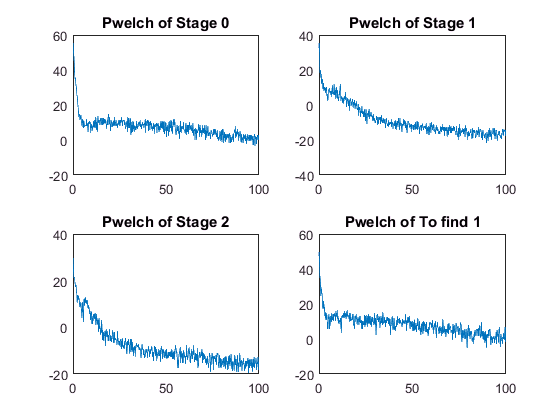

%find pwelch of part 6 and compare
% To find 1
[px1,freqx1] = pwelch(to_find.Data(:,1),[],[],[],fsx1);
figure(47)
subplot(2,2,1);
plot(freqw0,10*log10(pw0));
title('Pwelch of Stage 0');
subplot(2,2,2);
plot(freqw1,10*log10(pw1));
title('Pwelch of Stage 1');
subplot(2,2,3);
plot(freqw2,10*log10(pw2));
title('Pwelch of Stage 2');
subplot(2,2,4);
plot(freqx1,10*log10(px1));
title('Pwelch of To find 1');

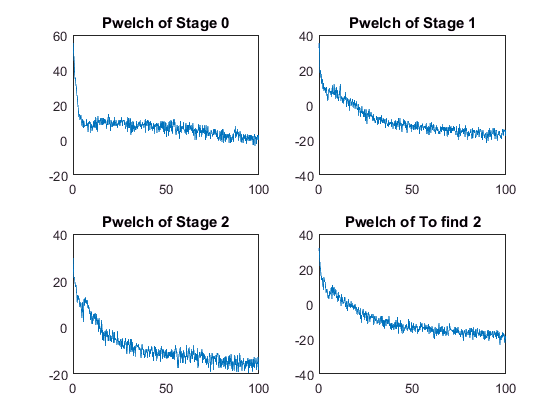

% To find 2
[px2,freqx2] = pwelch(to_find2.Data(:,1),[],[],[],fsx2);
figure(48)
subplot(2,2,1);
plot(freqw0,10*log10(pw0));
title('Pwelch of Stage 0');
subplot(2,2,2);
plot(freqw1,10*log10(pw1));
title('Pwelch of Stage 1');
subplot(2,2,3);
plot(freqw2,10*log10(pw2));
title('Pwelch of Stage 2');
subplot(2,2,4);
plot(freqx2,10*log10(px2));
title('Pwelch of To find 2');

% find power of each band for finds
%to find 1
px1d = sum(real(deltax1).^2);
px1t = sum(real(tetax1).^2);
px1a = sum(real(alphax1).^2);
px1b = sum(real(betax1).^2);
px1g = sum(real(gamax1).^2);
pxx1 = {'To find1' px1d px1t px1a px1b px1g};
%to find 2
px2d = sum(real(deltax2).^2);
px2t = sum(real(tetax2).^2);
px2a = sum(real(alphax2).^2);
px2b = sum(real(betax2).^2);
px2g = sum(real(gamax2).^2);
pxx2 = {'To find2' px2d px2t px2a px2b px2g};
disp('     Power       Delta       Teta       Alpha       Beta       Gama');

     Power       Delta       Teta       Alpha       Beta       Gama


disp(pxx1);

    'To find1'    [9.6976e+03]    [1.1509e+04]    [1.8633e+04]    [9.0079e+04]    [8.7304e+05]



disp(pxx2);

    'To find2'    [62.2957]    [113.3849]    [143.9103]    [643.3724]    [7.4119e+03]



disp(p0);

    'Stage 0'    [5.5188e+03]    [7.9914e+03]    [1.5529e+04]    [6.0035e+04]    [5.1187e+05]



disp(p1);

    'Stage 1'    [99.4084]    [156.3010]    [175.6388]    [809.6817]    [1.0118e+04]



disp(p2);

    'Stage 2'    [128.6468]    [171.7581]    [256.7347]    [1.0365e+03]    [9.5969e+03]



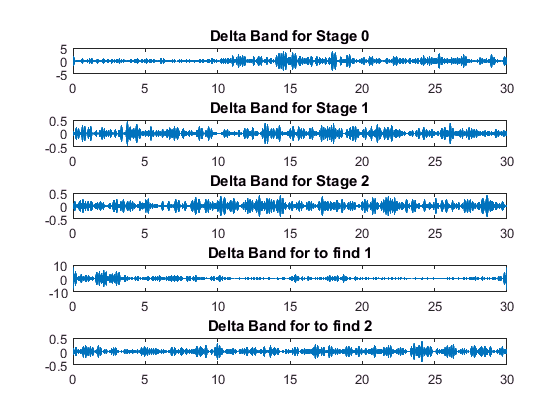

% compare each band for part 6
%Delta
figure(49)
subplot(5,1,1);
plot(t0,real(delta0));
title('Delta Band for Stage 0');
subplot(5,1,2);
plot(t1,real(delta1));
title('Delta Band for Stage 1');
subplot(5,1,3);
plot(t2,real(delta2));
title('Delta Band for Stage 2');
subplot(5,1,4);
plot(tx1,real(deltax1));
title('Delta Band for to find 1');
subplot(5,1,5);
plot(tx2,real(deltax2));
title('Delta Band for to find 2');

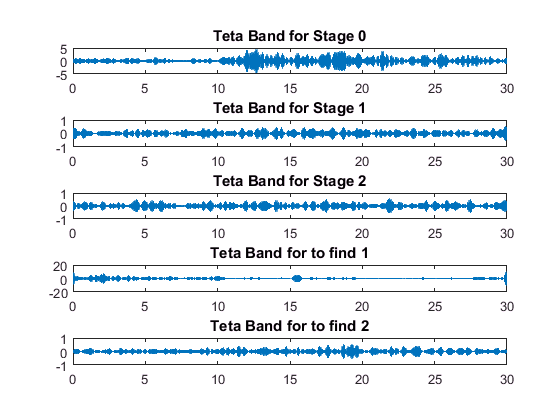

%Teta
figure(50)
subplot(5,1,1);
plot(t0,real(teta0));
title('Teta Band for Stage 0');
subplot(5,1,2);
plot(t1,real(teta1));
title('Teta Band for Stage 1');
subplot(5,1,3);
plot(t2,real(teta2));
title('Teta Band for Stage 2');
subplot(5,1,4);
plot(tx1,real(tetax1));
title('Teta Band for to find 1');
subplot(5,1,5);
plot(tx2,real(tetax2));
title('Teta Band for to find 2');

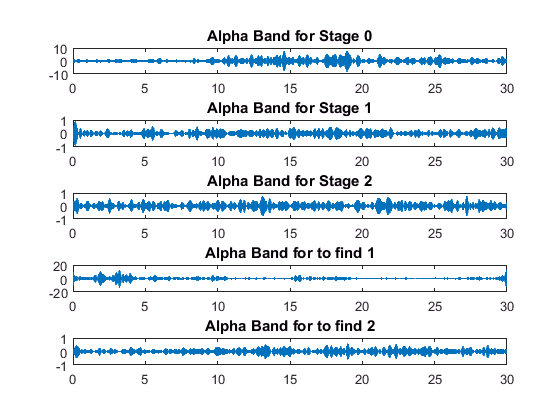

%Alpha
figure(51)
subplot(5,1,1);
plot(t0,real(alpha0));
title('Alpha Band for Stage 0');
subplot(5,1,2);
plot(t1,real(alpha1));
title('Alpha Band for Stage 1');
subplot(5,1,3);
plot(t2,real(alpha2));
title('Alpha Band for Stage 2');
subplot(5,1,4);
plot(tx1,real(alphax1));
title('Alpha Band for to find 1');
subplot(5,1,5);
plot(tx2,real(alphax2));
title('Alpha Band for to find 2');

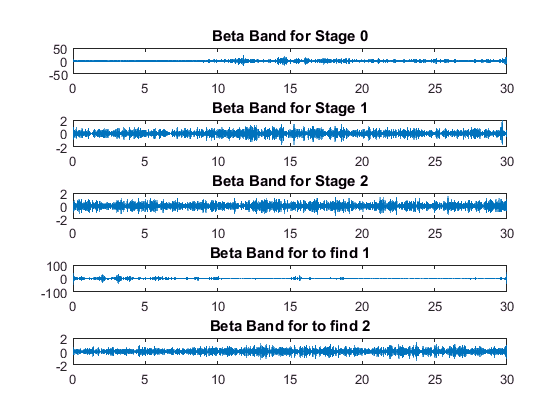

%Beta
figure(52)
subplot(5,1,1);
plot(t0,real(beta0));
title('Beta Band for Stage 0');
subplot(5,1,2);
plot(t1,real(beta1));
title('Beta Band for Stage 1');
subplot(5,1,3);
plot(t2,real(beta2));
title('Beta Band for Stage 2');
subplot(5,1,4);
plot(tx1,real(betax1));
title('Beta Band for to find 1');
subplot(5,1,5);
plot(tx2,real(betax2));
title('Beta Band for to find 2');

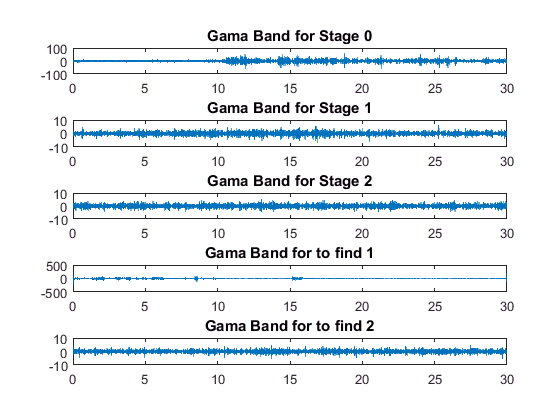

%Gama
figure(53)
subplot(5,1,1);
plot(t0,real(gama0));
title('Gama Band for Stage 0');
subplot(5,1,2);
plot(t1,real(gama1));
title('Gama Band for Stage 1');
subplot(5,1,3);
plot(t2,real(gama2));
title('Gama Band for Stage 2');
subplot(5,1,4);
plot(tx1,real(gamax1));
title('Gama Band for to find 1');
subplot(5,1,5);
plot(tx2,real(gamax2));
title('Gama Band for to find 2');

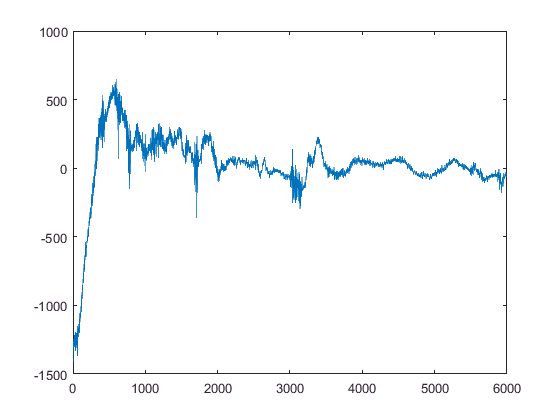

% part 6 plot the signals without filter
figure(54)
plot(to_find.Data(:,1))

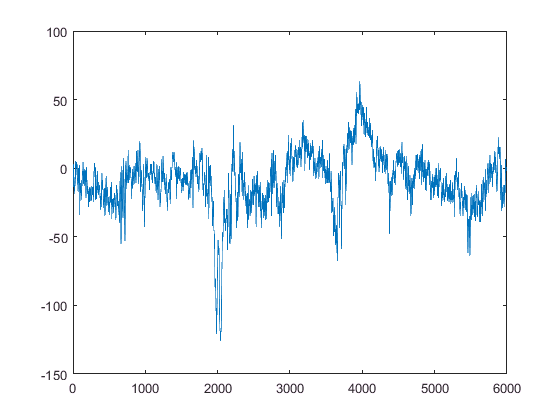

title('To find1 before filtering');
figure(55)
plot(to_find2.Data(:,1));

title('To find2 before filtering');